# Proyecto - Wireless 2022

#### Llorente, J. Fermín - P. Agustín Roncagliolo - CoMyS (E1605) 2022

## 1. Introducción

    La función CanalFlat.m provista genera realizaciones de la ganancia de un canal plano, con desvanecimiento Rayleigh, y espectro Doppler de acuerdo al modelo de Clarke. Devuelve en la variable `h` la ganancia compleja del canal con correlación *Jakes* normalizada para que tenga ganancia media unitaria. Esta ganancia es el equivalente a $c(\tau,t)$ para un $t$ dado. 

CanalFlat;

Una vez que se corrió el Script provisto, se puede graficar la magnitud de la ganancia de canal para los distintos retardos, siendo la misma una realización en un $t$ dado.

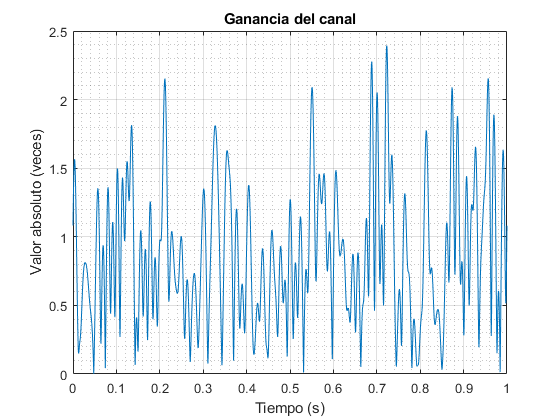

% Gráfica de la ganancia de canal
figure;
plot((0:N-1)*ts, abs(h)), grid on, grid minor;
title('Ganancia del canal'), ylabel('Valor absoluto (veces)'), xlabel('Tiempo (s)');

Además, es posible graficar el espectro *Doppler* de esta realización de canal. 

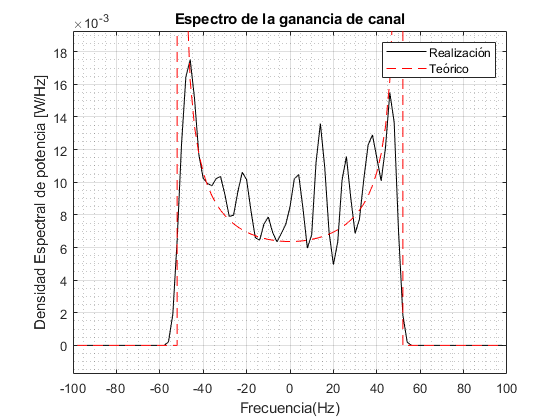

[DOP,ff] = pwelch(h,[],[],2*fr,fs);
S_a_neg = (ff>-fDm & ff<fDm).*1./(pi*fDm*sqrt(1-(ff/fDm).^2));  %Espectro Doppler teórico.
figure;
plot(ff,DOP,'k'), grid on, grid minor, hold on;
title('Espectro de la ganancia de canal'), ylabel('Densidad Espectral de potencia [W/Hz]'), xlabel('Frecuencia(Hz)');
ylim([-0.1*max(DOP) max(DOP)*1.1]);
plot(ff,S_a_neg,'--r');
legend('Realización','Teórico');

Ya sabemos que se define el *Power Delay Profile *o *Multipath Intensity Profile *como 

$A_c(\tau) \triangleq A_c(\tau,0) = \mathbb{E}\left\{ |c(\tau,t)^2| \right\}$.

De manera que si obtenemos $c(\tau,t_0)$ es necesario generar muchas realizaciones para poder calcular su esperanza y de esa manera obtener el *Power Delay Profile*. 

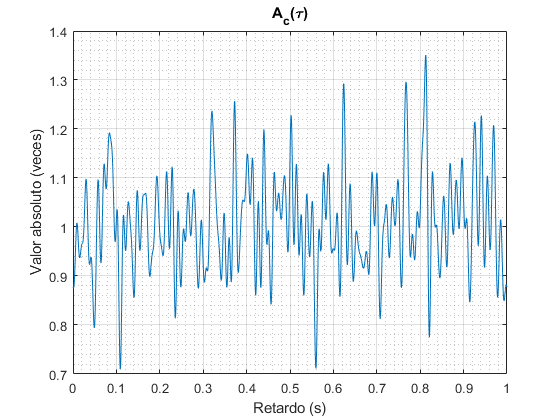

L = 100; %Realizaciones.
C = zeros(length(h),L);
C(:,1) = h;
for i=2:L
    CanalFlat;
    C(:,i) = h;
end
A_c = mean(abs(C).^2,2);
figure;
plot((0:N-1)*ts, A_c), grid on, grid minor;
title('A_c(\tau)'), ylabel('Valor absoluto (veces)'), xlabel('Retardo (s)');

    Si ahora se quiere calcular el *Delay Spread *$T_d
$ RMS (solo vale si consideramos que el *Rx* opera sincronizado a $\mu_T$), será necesario calcular la desviación estandar del *Power Delay Profile.*

T_d = sqrt(var(A_c))

T_d = 0.0973

Por este camino hay algo que estoy haciendo mal porque es muy pequeño, como máximo debería dar $T_d = 5\mu s
$ por enunciado.

    Si definimos 


$$C(f,t) = \int\limits_{-\infty}^{\infty}{c(\tau,t)e^{-j2\pi f\tau}d\tau}$$


Se puede obtener una función de autocorrelación particular (particular por donde es evaluada la misma) de esta caracterización $A_C(\Delta f,\Delta t)
$ que está definida como


$$A_C(\Delta f) \triangleq A_C(\Delta f,0) = TF_\tau\left\{ A_c(\tau) \right\}$$


El *ancho de banda de coherencia *es el soporte (en retardo de frecuencia) de la función de autocorrelación evaluada en retardo nulo en tiempo.

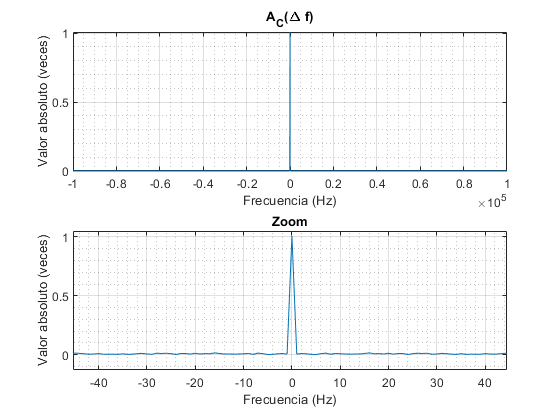

A_C_deltaf = fftshift(fft(A_c)*ts);
df = fs/length(A_c);
f = -fs/2 : df : fs/2 - df;
figure;
subplot(2,1,1);
plot(f,abs(A_C_deltaf)), grid on, grid minor;
title('A_C(\Delta f)'), ylabel('Valor absoluto (veces)'), xlabel('Frecuencia (Hz)');
subplot(2,1,2);
plot(f,abs(A_C_deltaf)), grid on, grid minor;
title('Zoom'), ylabel('Valor absoluto (veces)'), xlabel('Frecuencia (Hz)'), xlim([-45.3 44.5]), ylim([-0.13 1.05]);

    En este caso el ancho de banda de coherencia resulta cercano a 1 Hz, hay algo mal en lo que estoy haciendo porque es muy pequeño... Eso haría un *Delay Spread de *

$T_d = \frac{1}{2W_c} = 500 \ ms$    También muy chico!